## TCLab Step Test Simulation

Goal: Compare Step response data to simulated data from TCLab

Simplified dymanic model of TCLab:


$$\tau_p\frac{dT}{dt}=(T_a-T) +K_pQ$$


Compare the simulated temperature to the actual temperature change.

### Simulation

Simulate the change in temperature as the heater is set to 50% for 5 minutes

% clear code
clc;clear all;close all;

% initialize time
times=linspace(0,300, 301);

% simulate
[t, T] = ode45(@(t, T) simulate_TCLab(t, T), times, 23);

### TCLab Data Collection

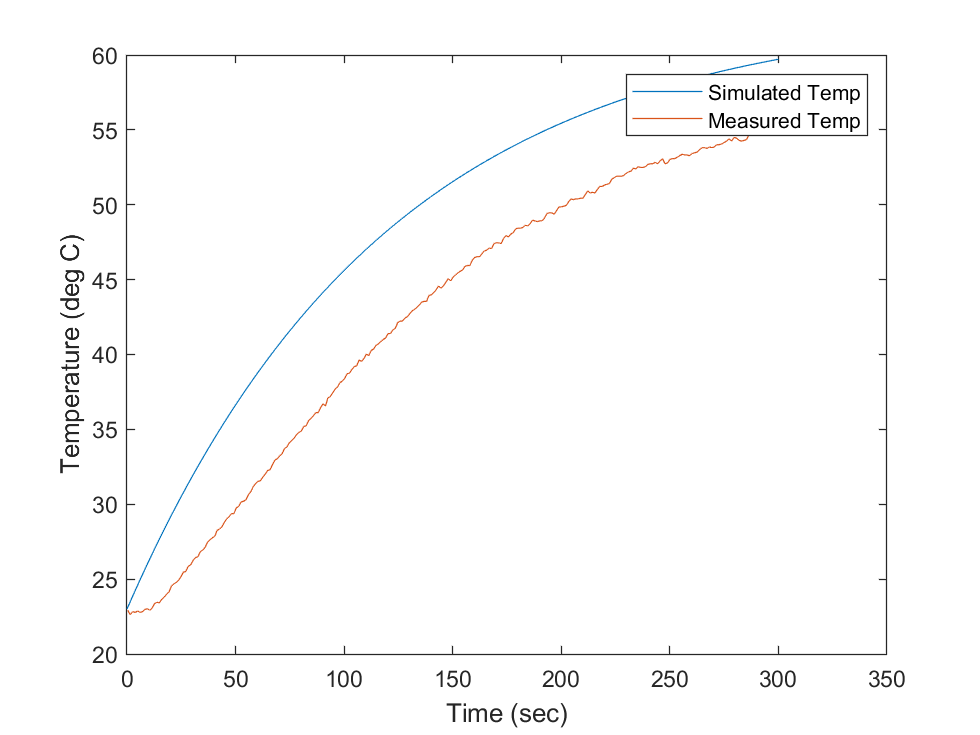

try
    % initialize storage array
    T1 = zeros(301, 1);
    tm = zeros(301, 1);
    
    % connect to TCLab
    lab = tclab;
    lab.Q1(50);
    tic;
    for i=1:length(times)
        T1(i) = lab.T1;
        tm(i) = toc;
        pause(1);
        
    end
    lab.off;
    clear lab;

catch
    lab.off;
    clear lab;
    
end

% plot results
plot(times, T)
hold on;
plot(tm, T1)
hold off;
xlabel('Time (sec)')
ylabel('Temperature (deg C)')
legend({'Simulated Temp', 'Measured Temp'})

function dTdt = simulate_TCLab(t, T)
% parameters
taup = 120; % Time Constant (sec)
Ta = 23;    % Ambient Temperature (deg C)
Kp = .8;    % Gain (deg C/ % power)
Q = 50;     % Percent power used
dTdt = ((Ta-T)+Kp*Q)/taup;
end
